%   Army ant scaffolding, fitting differential equation model to experimental data
%

close all
clear all

## Data parsing and grouping

%   This datasheet contains estimates of scaffold growth over time from replicates
%   at 50, 60, 70, 80, and 90 deg, at 1-second increments, extracted as follows:
growth_data = readtable('/Users/matthewlutz/Documents/MATLAB/Scaffolding_Growth_Data_ForModelFitting_FINAL.csv');

%   IDs for each experimental replicate, from column [1]
sessions = table2array(growth_data(:,1));

%   Angle of experimental platform theta (degrees), from column [2]
angles = table2array(growth_data(:,2));  

%   Count estimates of size over time (number of ants in the scaffold), from
%   multiplying output from the software in pixel area, column [3], 
%   by scaling factors derived for each replicate, column [7] 
scaffold_size_counts = ceil(table2array(growth_data(:,3)) .* table2array(growth_data(:,7)));
    
%   Experimental time in seconds, 0-600, column [4]
times = table2array(growth_data(:,4));

%   Mean overall rate of traffic (ants/s) for each replicate, column [5]   
traffics_mean = table2array(growth_data(:,5));  
    
%   Mean rate of prey transport (prey-laden ants/s) for each replicate, column [6]
preys_mean = table2array(growth_data(:,6));
   
%   Traffic rate (ants/s) at start of experiment, from 0-120s, column [9]
traffics_start = table2array(growth_data(:,9));
    
%   Traffic rate (ants/s) at middle of experiment, from 240-360s, column [10]
traffics_mid = table2array(growth_data(:,10));
    
%   Traffic rate (ants/s) at end of experiment, from 480-600s, column [11]
traffics_end = table2array(growth_data(:,11));

[sess, init, sessIdx] = unique(sessions);

%   Looping through to extract data for each experimental replicate 

for k = 1:46
    idx1 = init(k);
    idx2 = init(k) + 600;
    
    time{k} = times(idx1:idx2);
    scaffold_size{k} = scaffold_size_counts(idx1:idx2);
    traf_mean{k} = traffics_mean(idx1);
    traf_start{k} = traffics_start(idx1);
    traf_mid{k} = traffics_mid(idx1);
    traf_end{k} = traffics_end(idx1);
    prey{k} = preys_mean(idx1);
    angle{k} = angles(idx1);
end

## Fit model function to data from all experimental replicates

rng(0);
optimoptions(@lsqcurvefit, 'Algorithm', 'levenberg-marquardt');

figure

for k = 1:46     
    
%   For model fitting, count estimates of scaffold size over time are loaded, smoothed
%   to reduce noise from the algorithm, and filtered to avoid overfitting.

    x_data_time = time{k};
    y_data_size = smoothdata(scaffold_size{k}, 'movmedian', 10);
    x_10_data_time = x_data_time(1:10:end);
    y_10_data_size = y_data_size(1:10:end);
    
%   The model function @ScaffoldDynamics takes four known input parameters
%   - mu, beta, theta, prey_prop - derived from the loaded observations for
%   each replicate. 
% 
%   As described in Results, beta is fixed at a value determined after initially
%   varying it as another fitting parameter (to generate fitted estimates for beta,
%   its fixed value can be commented out, and values can be provided instead for
%   its initial guess and upper and lower bounds below).

    start_traf = traf_start{k};
    mid_traf = traf_mid{k};
    end_traf = traf_end{k};
    
    mu = traf_mean{k} - prey{k}; 
    theta = angle{k} * pi/180;
    prey_prop = prey{k} / traf_mean{k};
    beta = 0.0023;
    
%   Nonlinear least-squares optimization is performed to generate estimates
%   for parameters PcSS and S_0, fitting the model (function @ScaffoldDynamics)
%   to the data using lsqcurvefit solver (from Optimization Toolbox).
%
%   Since many local minima exist for this problem depending on starting
%   values, the solver is run repeatedly with different initial conditions
%   using MultiStart (from Global Optimization Toolbox) to try to find the best
%   global solution.
%
%   The input vector B_0 includes the four known parameters, along with starting
%   guesses for two unknown parameters to be fitted - PcSS (conditional
%   probability of stopping) and S_0 (initial surface slipperiness).
%
%   The vectors lb and ub give lower and upper bounds to constrain the parameters
%   to be fitted within feasible ranges. Known parameters mu, beta, theta,
%   and prey_prop are given bounds equal to their values from the data,
%   and thus considered as fixed.

    B_0 = [mu, beta, theta, prey_prop, .41, .06];
    lb = [mu, beta, theta, prey_prop, .15, .0001];
    ub = [mu, beta, theta, prey_prop, .95, .24];

    problem = createOptimProblem('lsqcurvefit', 'x0', B_0, ...
        'objective', @ScaffoldDynamics, 'lb', lb, 'ub', ub, ...
        'xdata', x_10_data_time, 'ydata', y_10_data_size);
   
    ms = MultiStart('UseParallel', true, 'Display', 'off');

    [B_ms, fval, eflag, ~, manymins] = run(ms, problem, 100);
    
    [B, resnorm, residual, ~, output] = lsqcurvefit(@ScaffoldDynamics, ...
        B_ms, x_10_data_time, y_10_data_size, lb, ub);

    fitResults.mu(k) = B(1);
    fitResults.beta(k) = B(2);
    fitResults.theta(k) = B(3);
    fitResults.prey_prop(k) = B(4);
    fitResults.PcSS(k) = B(5);
    fitResults.S_0(k) = B(6);
    fitResults.traf_start(k) = start_traf;
    fitResults.traf_mid(k) = mid_traf;
    fitResults.traf_end(k) = end_traf;
    fitResults.resnorm(k) = resnorm;
    fitResults.residual(k,:) = residual;
    fitResults.SStotal(k) = (length(y_10_data_size) - 1) * var(y_10_data_size);
    fitResults.Rsquared(k) = 1 - (resnorm / fitResults.SStotal(k));

    times = linspace(x_10_data_time(1), x_10_data_time(end));
    
    Model_Size = ScaffoldDynamics(B, times);
    fitResults.AntsJoin_0_120(k) = Model_Size(20);
    fitResults.AntsJoin_480_600(k) = Model_Size(100) - Model_Size(80);
    
    Model_S = ScaffoldDynamics_BothOutputs(B, times);
    fitResults.S_60(k) = Model_S(10);
    fitResults.S_120(k) = Model_S(20);
    fitResults.S_480(k) = Model_S(80);
    fitResults.S_540(k) = Model_S(90);
    fitResults.S_600(k) = Model_S(100);
    
%   This plots all the fitted curves over the observations for each replicate

    plot(x_10_data_time, y_10_data_size, 'o', times, ...
        ScaffoldDynamics(B, times), 'b-', 'linewidth', 1)
    hold on
    
    Ys{k} = y_10_data_size;
    Yf{k} = ScaffoldDynamics(B, times);
end


Local minimum possible.
lsqcurvefit stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>

Local minimum possible.
lsqcurvefit stopped because the size of the current step is less than
the value of the step size tolerance.

<

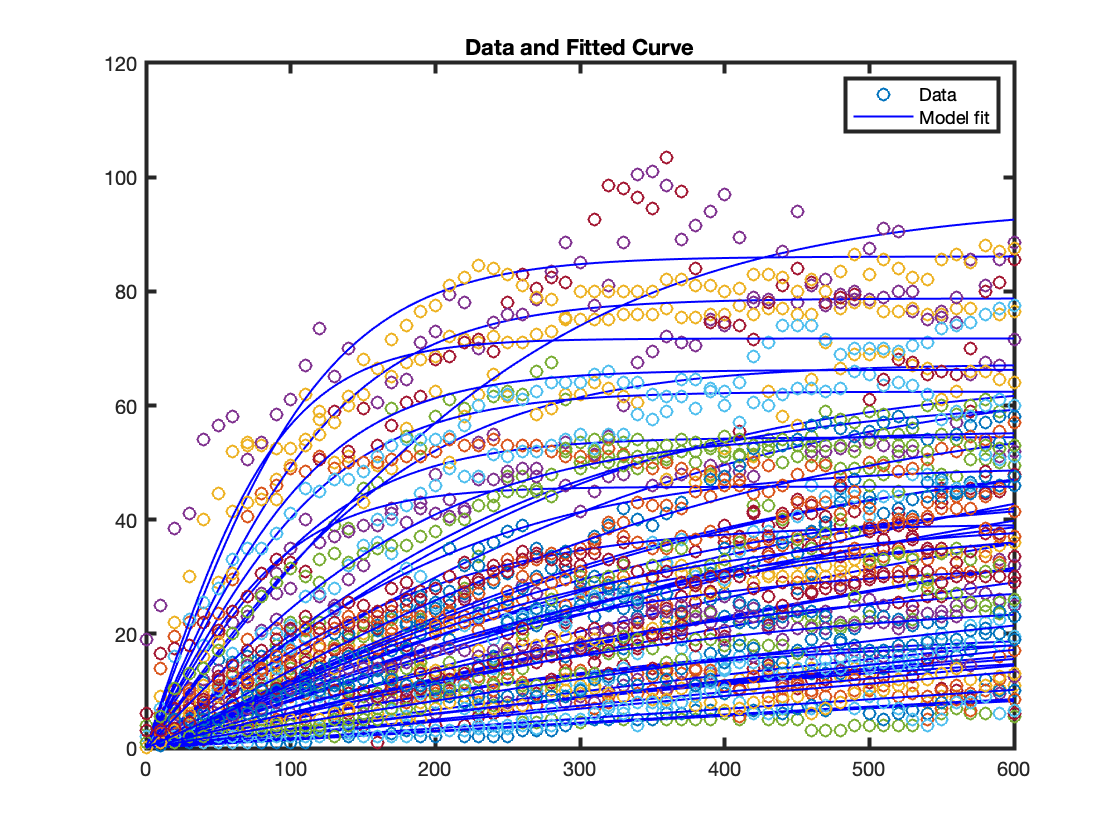


legend('Data','Model fit');
title('Data and Fitted Curves');

set(gca,'linewidth',2);

set(gcf,'color','w');

fitResults.angle = cellfun(@(v)v(1), angle);
fitResults.sessions = sess';
fitResults.size_obs = scaffold_size;
fitResults.time = time;

## Additional plots for each angle individually


figure

%   Change this value for each desired angle
X = 90;

length(X);

clear Yss Yff

for k = 1:length(X)

    Yss = cell2mat(Ys(fitResults.angle==X(k)));
    Yff = cell2mat(Yf(fitResults.angle==X(k)));
    
    plot(x_data,Yss','o')
    hold on
    plot(times,Yff','-')
    
    xlim([0 600])
    ylim([0 100])
end

set(gca,'linewidth',2)
set(gcf,'color','w')

## Plot for Figure 4b - Model predictions vs. observed estimates for S

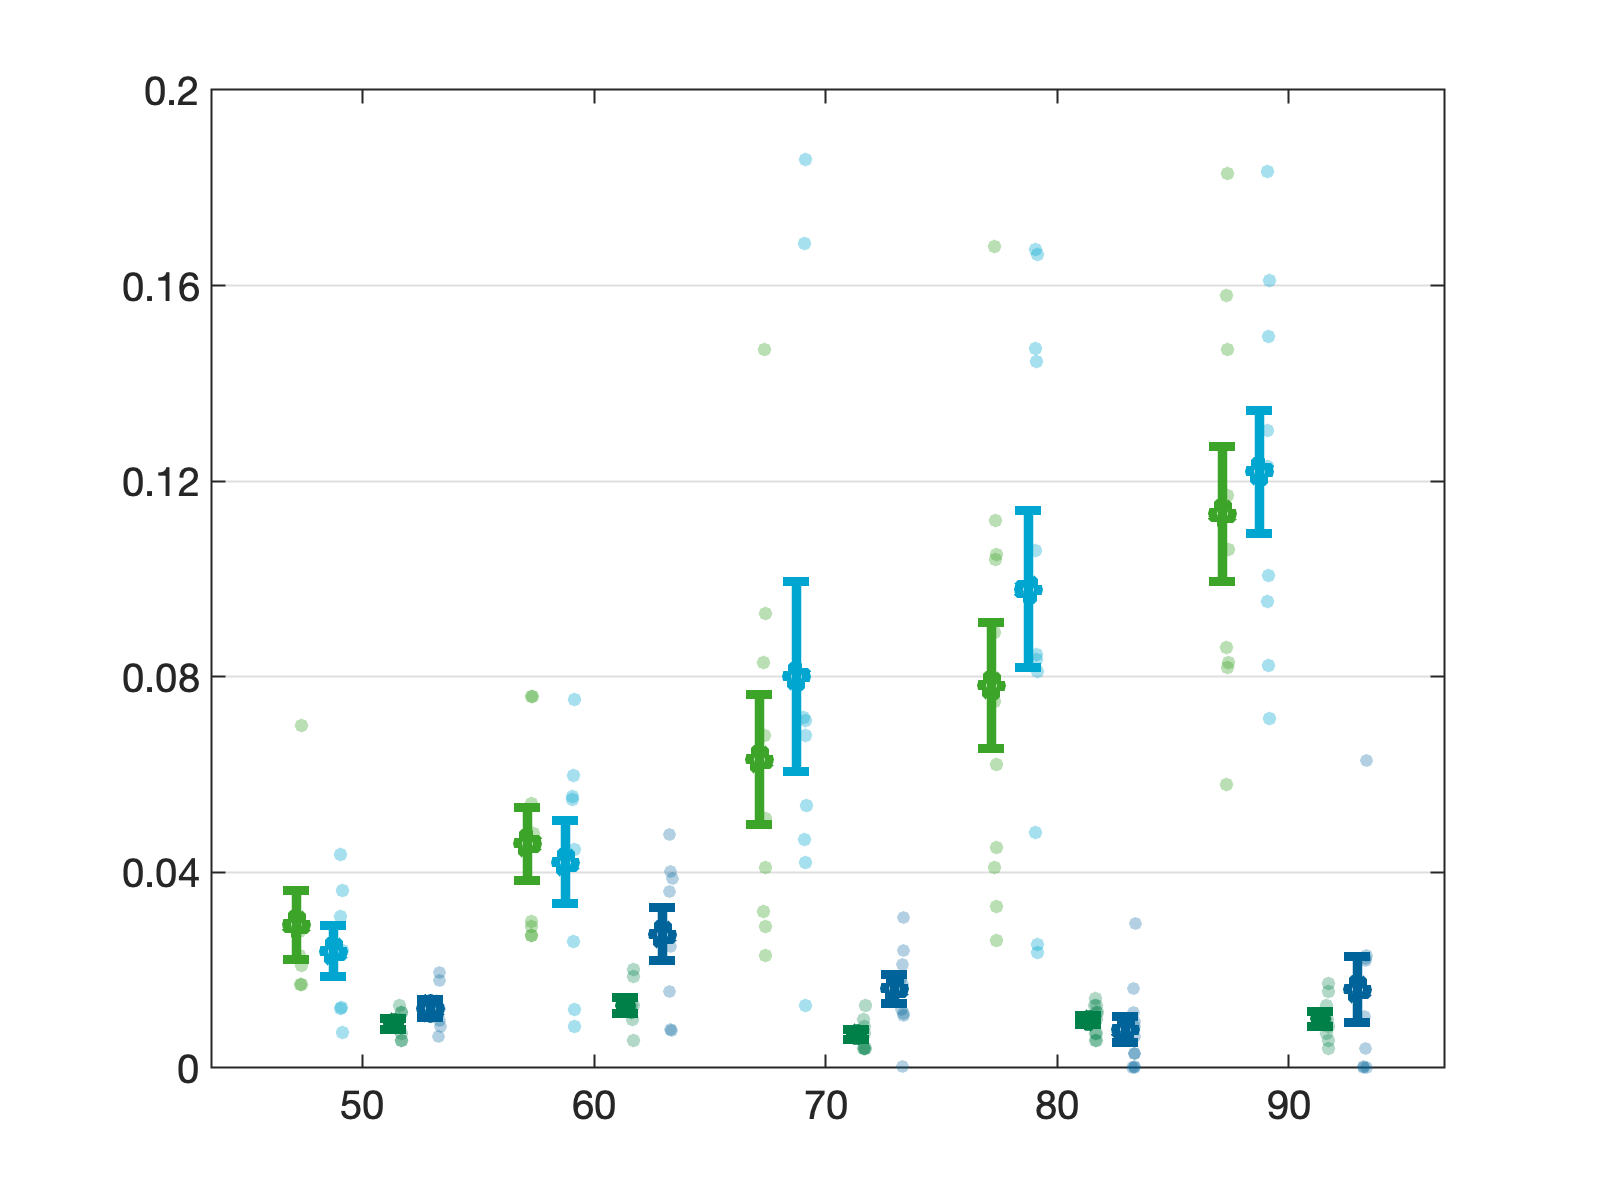


%   For this section, I manually imported the following columns from the
%   datasheet "Main_DataSheet_Scaffolding_50_above_FINAL.csv" as vectors,
%   for comparisons with model predictions shown in the plot:
%
%   Slip_Falls_Start
%   Slip_Falls_End
%   P_Slip
%
%   (code to be updated soon to load these from the datasheet 
%   automatically, as above)

p = figure;

green_light = [61 165 42] / 256;
green_dark = [0 129 73] / 256;
blue_light = [0 167 208] / 256;
blue_dark = [0 100 156] / 256;

%   Calculating mean and median values for predicted values of S from model
%   at start and end

S_start_mean = mean([fitResults.S_0; fitResults.S_60; fitResults.S_120]);
S_start_median = median([fitResults.S_0; fitResults.S_60; fitResults.S_120]);
S_end_mean = mean([fitResults.S_480; fitResults.S_540; fitResults.S_600]);
S_end_median = median([fitResults.S_480; fitResults.S_540; fitResults.S_600]);

%   Estimates of total ants crossing and P_S from observations

ants_across_0_120 = fitResults.traf_start .* 120;
ants_across_480_600 = fitResults.traf_end .* 120;
P_S_end_observed = (fitResults.AntsJoin_480_600 + SlipFalls_End) / ants_across_480_600;

%   START: 0-120s
%   plotting observations of P_S (light green)
%   vs. 
%   predictions of S (light blue)

yy = S_start_mean;
xx = P_Slip;
X = [50:10:90];
XX = [50:10:90];

for k = 1:5
    Y(k) = mean(yy(fitResults.angle==X(k)));
    Yerr(k) = std(yy(fitResults.angle==X(k))) / (sqrt(length(yy(fitResults.angle==X(k)))));
end

errorbar(X - 1.25, Y, Yerr, 'o', 'MarkerSize', 10, 'linewidth', 4.8, 'color', blue_light, 'CapSize', 11);
hold on
scatter(fitResults.angle - 0.9, S_start_mean, 48, 'MarkerFaceColor', blue_light, 'MarkerEdgeColor', blue_light, 'MarkerFaceAlpha', 0.35,'MarkerEdgeAlpha', 0, 'jitter', 'on', 'jitterAmount', 0.075);
hold on

for k = 1:5
    YY(k) = mean(xx(Angle==XX(k)));
    YYerr(k) = std(xx(Angle==XX(k))) / (sqrt(length(xx(Angle==XX(k)))));
end

errorbar(XX - 2.86, YY, YYerr, 'o', 'MarkerSize',10,'linewidth', 4.8, 'Color', green_light, 'CapSize', 11)
hold on
scatter(Angle - 2.65, P_Slip, 48, 'MarkerFaceColor', green_light, 'MarkerEdgeColor', green_light, 'MarkerFaceAlpha', 0.35,'MarkerEdgeAlpha', 0, 'jitter', 'on', 'jitterAmount', 0.075)
hold on

%   END: Adding comparisons from 480-600s
%   plotting observations of P_S (dark green) 
%   vs.
%   model predictions of S (dark blue

yy = S_end_mean;
xx = P_S_end_observed;
X = [50:10:90];
XX = [50:10:90];

for k = 1:5
    Y(k) = mean(yy(fitResults.angle==X(k)));
    Yerr(k) = std(yy(fitResults.angle==X(k)))/(sqrt(length(yy(fitResults.angle==X(k)))));
end

errorbar(X + 2.95, Y, Yerr, 'o', 'MarkerSize', 10, 'linewidth', 4.8, 'color', blue_dark, 'CapSize', 11)
hold on
scatter(fitResults.angle + 3.3, S_end_mean, 43, 'MarkerFaceColor', blue_dark, 'MarkerFaceAlpha', 0.3, 'MarkerEdgeColor', blue_dark,'MarkerEdgeAlpha', 0, 'jitter', 'on', 'jitterAmount', 0.075)
clc
hold on 

for k = 1:5 
    YY(k) = mean(xx(Angle==XX(k)));     % mean for each angle
    YYerr(k) = std(xx(Angle==XX(k))) / (sqrt(length(xx(Angle==XX(k)))));     % SEM for each angle
end

errorbar(XX + 1.35, YY, YYerr, 'o', 'linewidth', 4.8, 'Color', green_dark, 'CapSize', 11)
hold on
scatter(Angle + 1.65, P_S_end_observed, 48, 'MarkerFaceColor', green_dark, 'MarkerFaceAlpha', .3, 'MarkerEdgeColor', green_dark, 'MarkerEdgeAlpha', 0, 'jitter', 'on', 'jitterAmount', .075)
hold on

x0 = 10;
y0 = 10;
width = 800;
height = 600;

set(gcf,'position',[x0,y0,width,height], 'color','w');
set(gca,'linewidth',1, 'YGrid', 'on', 'FontSize', 20);

xlim([43.5, 96.7]);
ylim([0, 0.20]);
yticks([0 0.04 0.08 0.12 0.16 0.20]);

pbaspect([1.26 1 1]);


% Export as .png or .pdf
    % exportgraphics('reduction_S_overTime.png', 300)
    % exportgraphics(p, 'Figure4b_NEW.pdf','ContentType','vector')